# **Fase 2: Diseño directo del regulador**

**Parámetros iniciales:**

clear

Ts = 0.035;
ts = 0.980;
errp = 0.03;
BoG = zpk([],0.8752, 0.0251, Ts);


$$BoG(z) = \frac{0.0251}{z - 0.8752} \left[\frac{m/s}{V}\right]$$


### **Ejercicio 6: Calcular la FdeT del regulador con el método directo Truxal.**

**Comprobar si es aplicable (Estabilidad y entrada escalón):**

- Todos los factores del EQD están dentro de la circunferencia unitaria -> Es estable.

- Tiene entrada escalón.

El modelo es **aplicable**.

**Planteamiento del modelo, aplicación de la especificación dinámica:**

ks = ceil(ts/Ts);
fprintf('La ks es: %.4f.\n', ks)

La ks es: 28.0000.


mod_p = exp(-3/ks);
fprintf('El módulo del polo es: %.4f.\n', mod_p)

El módulo del polo es: 0.8984.



$$M(z) = \frac{km}{z - 0.8984} \left[\frac{m/s}{m/s}\right]$$


**Chequeo de la causalidad:**


$$gD_{BG} - gN_{BG} \leq gD_M - gN_M$$



$$1 - 0 \leq 1 - 0$$


Se cumple que el regulador es **causal**.

**Aplicación de la especificación estática: **errp = 3%.


$$M(z) = R - errp = 1 - 0.03 = \lim_{z \to 1} \frac{km}{z - 0.8984}$$


km = (1 - 0.03) * (1 - 0.8984);
fprintf('La km es: %.4f.\n', km)

La km es: 0.0986.



$$km = 0.0986 \left[\frac{m/s}{m/s}\right]$$


**Modelo final:**

Mz = zpk([],0.8984, 0.0986, Ts);


$$M(z) = \frac{0.0986}{z - 0.8984} \left[\frac{m/s}{m/s}\right]$$



$$N_{BG} = 0.0251; \qquad D_{BG} = z - 0.8752;$$



$$N_M = 0.0986; \qquad D_M = z - 0.8984;$$



$$F(z) = \frac{N_F}{D_F} = \frac{M}{BG \cdot (1 - M)} = \frac{N_M \cdot D_{BG}}{N_{BG} \cdot (D_M - N_M)} = \frac{0.0986z - 0.0863}{0.0251z - 0.0250} \left[\frac{V}{m/s}\right]$$



$$F(z)= \frac{A(z)}{E(z)} =\frac{0.0986 - 0.0863z^{-1}}{0.0251 - 0.0250z^{-1}} = \frac{3.9283 - 3.4382z^{-1}}{1 - 0.9960z^{-1}} \left[\frac{V}{m/s}\right]$$



$$a[k] = 0.9960 \cdot a[k-1] + 3.9283 \cdot e[k] - 3.4382 \cdot e[k - 1]$$


### Ejercicio 7: Dibujar el diagrama de bloques del sistema.

%open_system('diagramaBloques.slx')

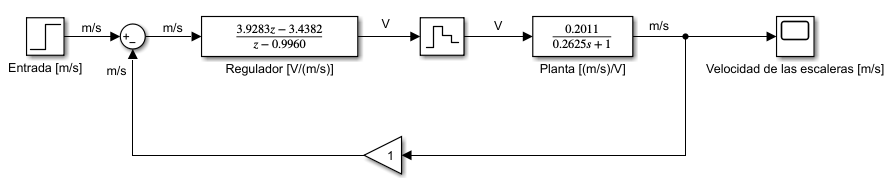

### **Ejercicio 8: Calcular la FdeT del sistema y caracterizar su salida a entradas escalón **±** 1 m/s.**

**FdeT del sistema:**

Fz = tf(minreal(Mz / (BoG * (1 - Mz))));


$$F(z)= \frac{3.928z - 3.438}{z - 0.997} \left[\frac{V}{m/s}\right]$$


Mz = minreal(feedback(series(Fz, BoG), 1));


$$M(z) = \frac{0.0986}{z - 0.8984} \left[\frac{m/s}{m/s}\right]$$


**Entrada escalón +1m/s:**


$$c(\infty) = R \cdot \lim_{z \to 1} \frac{0.0986}{z - 0.8984} = 1 \cdot 0.9705 = 0.9705 m/s$$


**Entrada escalón -1m/s:**


$$c(\infty) = R \cdot \lim_{z \to 1}  \frac{0.0986}{z - 0.8984} = -1 \cdot 0.9705 = -0.9705 m/s$$


### Ejercicio 9: Acción de control y velocidad de la escalera en régimen permanente.

Se ha creado una función "escalera" que realiza las siguientes operaciones:

- Entradas: BoG, Fz, Entrada escalón, Perturbación. 

- Salidas: c(∞) y a(∞).


$$c(\infty) = R \cdot k_0[M(z)_{escalón}] - Perturbación \cdot k_0[M(z)_{perturbación}]$$



$$A(\infty) = \frac{c(\infty) + Perturbacion}{ko[BoG]}$$


**Velocidad de la escalera y Acción de control con 0 personas:**

Entrada +1 m/s:

escalera(BoG, Fz, 1, 0);

La salida con entrada escalón 1 m/s y perturbación 0.0 m/s es: 0.9705 m/s.
La señal de acción con entrada escalón 1 m/s y perturbación 0.0 m/s es: 4.8253 V.


Entrada -1 m/s:

escalera(BoG, Fz, -1, 0);

La salida con entrada escalón -1 m/s y perturbación 0.0 m/s es: -0.9705 m/s.
La señal de acción con entrada escalón -1 m/s y perturbación 0.0 m/s es: -4.8253 V.


**Velocidad de la escalera y Acción de control con 5 personas:**

Entrada +1 m/s:

escalera(BoG, Fz, 1, 0.1);

La salida con entrada escalón 1 m/s y perturbación 0.1 m/s es: 0.9675 m/s.
La señal de acción con entrada escalón 1 m/s y perturbación 0.1 m/s es: 5.3078 V.


Entrada -1 m/s:

escalera(BoG, Fz, -1, 0.1);

La salida con entrada escalón -1 m/s y perturbación 0.1 m/s es: -0.9734 m/s.
La señal de acción con entrada escalón -1 m/s y perturbación 0.1 m/s es: -4.3428 V.


**Velocidad de la escalera y Acción de control con 10 personas:**

Entrada +1 m/s:

escalera(BoG, Fz, 1, 0.2);

La salida con entrada escalón 1 m/s y perturbación 0.2 m/s es: 0.9646 m/s.
La señal de acción con entrada escalón 1 m/s y perturbación 0.2 m/s es: 5.7904 V.


Entrada -1 m/s:

escalera(BoG, Fz, -1, 0.2);

La salida con entrada escalón -1 m/s y perturbación 0.2 m/s es: -0.9764 m/s.
La señal de acción con entrada escalón -1 m/s y perturbación 0.2 m/s es: -3.8602 V.


**Conclusión:**

Cuanto más personas se suben a la escalera, mayor es el peso que ejercen: 

- En el caso de la subida, la señal de acción aumenta dado que se necesita más energía para mover la escalera y que se mantenga constante la velocidad. 

- En el caso de la bajada, cuando mayor es el peso, más facilidad tiene la escalera para bajar, por lo que la señal de control disminuye (en módulo) para que pueda mantenerse constante la velocidad. 